# Resolución de Casos 1

### Parte 1 - Conversión de imagen a escala de grises.

1. Leemos una imagen.

imagen_parte_1 = imread("imagen.jpg", "jpg");

2. Guardamos las dimensiones de la imagen.

dimensiones = size(imagen_parte_1)

dimensiones =    332   720     3


3. Creamos una matriz para almacenar la imagen en escala de grises.

imagen_gris = zeros(dimensiones(1), dimensiones(2)); %#ok<PREALL>

4. Calculamos el valor de gris para cada píxel.

imagen_gris = 0.2989 * imagen_parte_1(:, :, 1) + 0.5870 * imagen_parte_1(:, :, 2) + 0.1140 * imagen_parte_1(:, :, 3);

5. Mostramos la imagen resultante.

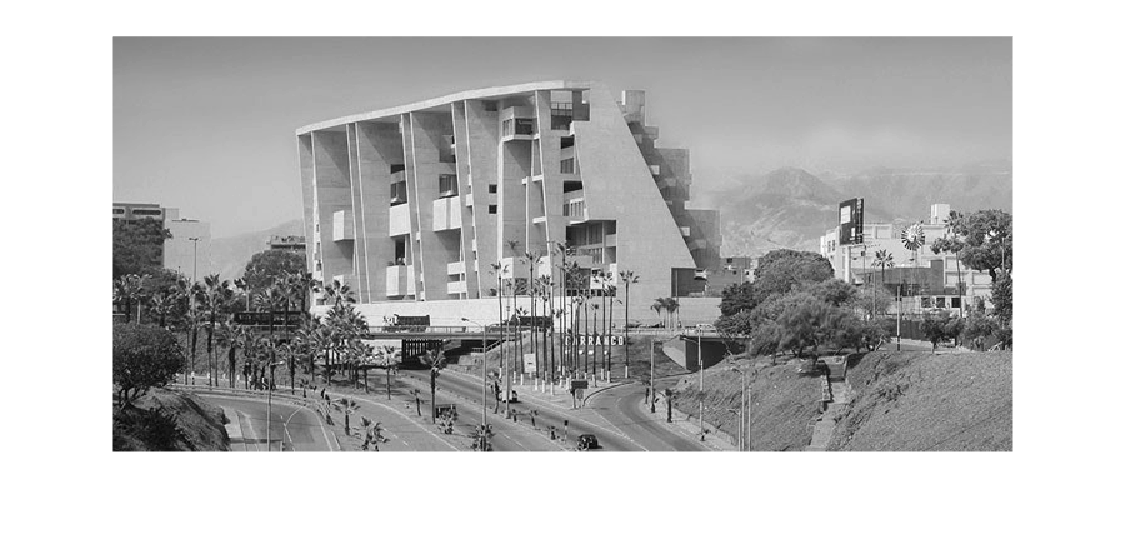

imshow(imagen_gris)

### Parte 2 - Ajuste de brillo y contraste de una imagen

1. Leemos una imagen.

imagen_parte_2 = imread("imagen.jpg", "jpg");

2. Elegimos los valores para el ajueste de brillo y de contraste.

brightness = 0.5;
contrast = 1.5;

3. Transformamos los pixeles de la imagen original.

imagen_modificada = (imagen_parte_2 * 1.5) + (0.5 * 255);

6. Mostramos la imagen.

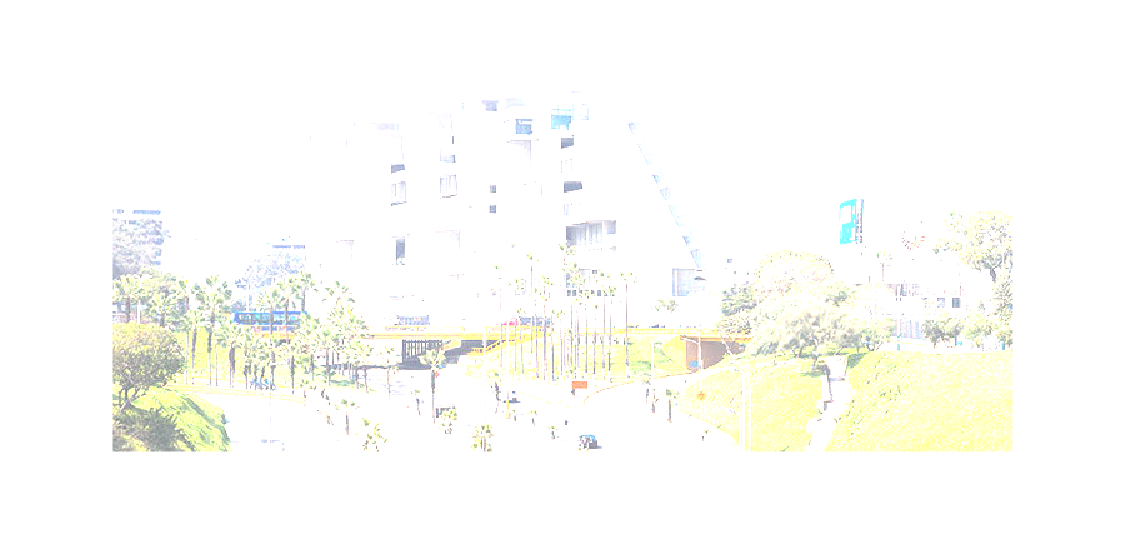

imshow(imagen_modificada)

### Parte 3 - Convolución

0. Definimos una matriz *filtro.*

filtro = zeros(3, 3);

1. Utilizamos la matriz *imagen_gris *como punto de partida.

2. Rellenamos de ceros el borde la matriz y definimos una nueva matriz *imagen_gris_au.*

imagen_gris_au = zeros(size(imagen_gris) + 2);
imagen_gris_au(2 : end - 1, 2 : end - 1) = imagen_gris

imagen_gris_au =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0   132   132   132   132   132   132   132   132   132   132   132   132   132   132   132   132   133   133   133   133   134   134   134   134   133   134   134   134   134   134   134   134   136   136   136   136   136   136   136   136   136   136   136   136   136   136   136   136   136
     0   132   132   132   132   132   132   132   132   133   133   133   133   133   133   133   133   133   133   133   133   134   134   134   134   134   134   134   134   134   134   134   134   136   136   136   136   136   136   136   136   137   137   137   137   137   137   137   137   136
     0   132   132   132   132   132   132   132   132   133   133   133   133  

3. Realizamos una operación de convolución a la matriz *imagen_gris_au *utilizando la matriz *filtro.*

[imagen_gris_alto, imagen_gris_ancho] = size(imagen_gris);
imagen_convolucion = zeros(imagen_gris_alto, imagen_gris_ancho);

for i = 1 : imagen_gris_alto
    for j = 1 : imagen_gris_ancho
        region = imagen_gris_au(i : i + size(filtro, 1) - 1, j : j + size(filtro, 2) - 1);

        imagen_convolucion(i, j) = sum(sum(region .* filtro));
    end
end

### Parte 4 - División de una imagen en subimágenes

1. Leemos un imagen y guardamos sus dimensiones.

imagen_parte_4 = imread("imagen.jpg", "jpg");
[imagen_altura, imagen_anchura, ~] = size(imagen_parte_4);

2. Definimos el número de filas y columnas de la cuadrícula de subimágenes.

filas_de_cuadricula = 2;
columnas_de_cuadricula = 2;

3. Calculamos las dimensiones de cada subimagen.

altoSubimagen = imagen_altura / filas_de_cuadricula;
anchoSubimagen = imagen_anchura / columnas_de_cuadricula;

4. Creamos una matriz para almacenar las subimágenes

subimagenes = cell(filas_de_cuadricula, columnas_de_cuadricula)

subimagenes = 2×2 cell array
    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}


5. Utilizamos bucles anidados para iterar a través de las filas y columnas de la cuadrícula. Para cada subimagen, se calculan las coordenadas de inicio y fin en la imagen original y se almacena la subimagen en la matriz de celdas.

for i = 1 : filas_de_cuadricula
    for j = 1 : columnas_de_cuadricula
        inicioFila = 1 + (i - 1) * altoSubimagen;
        finFila = i * altoSubimagen;
        
        inicioColumna = 1 + (j - 1) * anchoSubimagen;
        finColumna = j * anchoSubimagen;
        
        subimagenes{i, j} = imagen_parte_4(inicioFila:finFila, inicioColumna:finColumna, :);
    end
end

6. Mostramos las subimágenes en una cuadrícula.

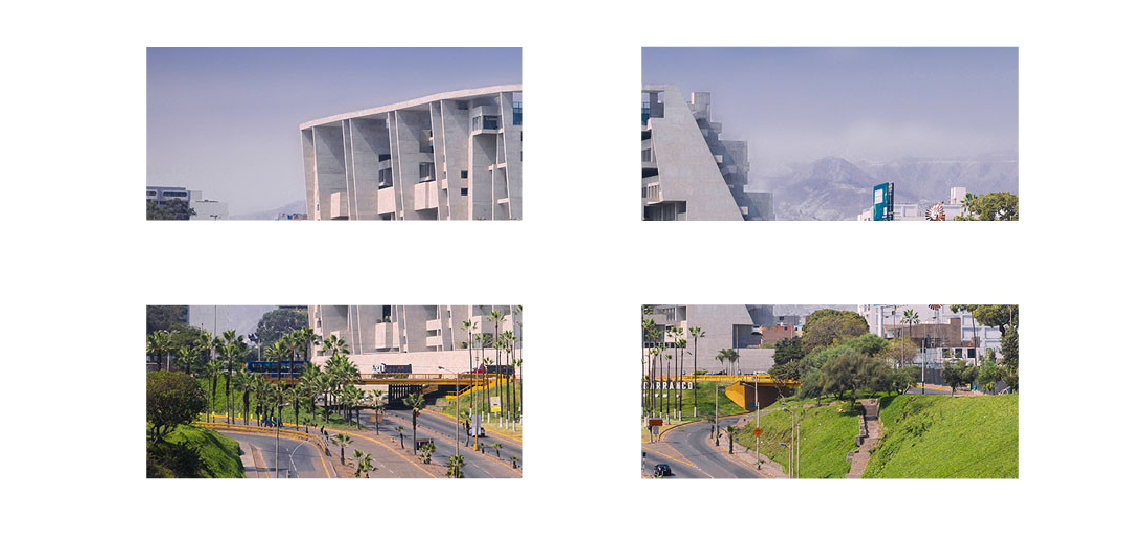

for i = 1 : filas_de_cuadricula
    for j = 1 : columnas_de_cuadricula
        subplot(filas_de_cuadricula, columnas_de_cuadricula, (i - 1) * columnas_de_cuadricula + j)
        imshow(subimagenes{i, j})
    end
end

### Preguntas adicionales

#### Ejercicio 1

El siguiente código sirve para aplicar un difuminado utilizando un relleno adecuado. Primero aplicaremos un relleno de tamaño 25 y de color aleatorio a la imagen usando el siguiente código.

function border = aplicar_relleno(obj)
    [m n o] = size(obj) % para completar
    border_width = 25; %para completar
    border = zeros(m+(border_width*2),n+(border_width*2),3);
    c = [randi(255) randi(255) randi(255)]; %para completar
    border(:,:,1) = c(1);
    border(:,:,2) = c(2);
    border(:,:,3) = c(3);
    for i = 1 : m
        for j = 1 : n
            border(i+border_width,j+border_width,:) = (obj(i,j,:));
        end
    end
end

En este caso, usaremos una matriz cuadrada *A* de orden 13 para el filtro.

lista_3d = leer_imagen(’https://th.bing.com/th/id/R.06ab389aa05724868c09d806abedd52a?rik=3h2YlcwV0qArCA&riu=http%3a%2f%2fimages6.fanpop.com%2fimage%2fphotos%2f40200000%2fDragon-dragons-40278823-695-960.jpg&ehk=jsMTUuIK71Qw%2bRk9VYQaI%2f2KZjV3vV8GHYLjkAfkkY8%3d&risl=&pid=ImgRaw&r=0%22%20#url%20de%20la%20imgen’);
lista_3d
guardar_imagen(’eg_utec.bmp’, aplicar_difuminado(lista_3d));
imshow(’eg_utec.bmp’)
function result = aplicar_difuminado(obj)
% SU SOLUCION EMPIEZA AQUI
A = ones(13,13)/169 % Esto es para completar
result = imfilter(obj,A)
% SU SOLUCION TERMINA AQUI
end
function lista_3d = leer_imagen(ruta)
% La funci´on leer_imagen recibe una cadena con la ruta
% de una imagen en formato BMP y devuelve una matriz
% tridimensional con el mapa de bits de la imagen.
% Convertimos la matriz a un tipo de dato com´un en lugar de usar la librer´ıa numpy.
img = imread(ruta);
lista_3d = int32(img);
end
function guardar_imagen(ruta, lista_3d)
% La funci´on guardar_imagen recibe una matriz tridimensional
% con el mapa de bits de la imagen y la guarda en formato bmp.
imwrite(uint8(lista_3d), ruta);
end